## Aula Teórica 21/11/2023 - Robótica

clear; clc
import RoboticaBiblioteca.*

printListaManipuladores()

--------------------> Lista de Manipuladores <-----------------------
1 - Manipulador Cartesiano: PPP
   1.1 - Manipulador Pórtico: cartesianos, mas com base em suportes
2 - Manipulador Cilíndrico: RPP
3 - Manipulador Articulados/Antropomórficos: RRR
4 - Manipulador Esféricos/Polares: RRP
5 - Manipulador SCARA: RRP, diferente do esférico, tem três eixos z0,
                       z1 e z2 todos verticais e paralelos


### EXERCÍCIO 1

theta(t) = C0 + C1t + C2t^2 + C3t^3

Condição inicial: t = 0s --> 30° (posição)

30° = C0 + C1*0 + C2*0^2 + C3*0^3       --> C0 = 30°

Condição final: t = 5s --> 75° (posição)

75° = 30 + C1*5 + C2*5^2 + C3*5^3

45° = C1*5 + C2*5^2 + C3*5^3  --> 25*C2 + 125*C3 = 45      Equação (1)

Derivada 1ª de theta(t)

theta_ponto(t) = C1 + 2*C2*t + 3*C3*t^2

Condição inicial: t = 0 --> 0°/s (velocidade)

0°/s = C1 + 2*C2*0 + 3*C3*0^2 ---> C1 = 0

Condição inicial: t = 5 --> 0°/s (velocidade)

0°/s =  2*C2*5 + 3*C3*5^2

10*C2 +75*C3 = 0              Equação (2) 

Sistema (Equações 1 e 2)

25*C2 + 125*C3 = 45

10*C2 + 75*C3 = 0

% [25, 125; 10, 75]*[C2; C3] = [45; 0]
C = inv([25, 125; 10, 75]) * [45; 0]

C =     5.4000
   -0.7200


C2 = 5.4

C3 = -0.72

M = coef3(30, 75, 5)

M =    30.0000
   -0.0000
    5.4000
   -0.7200


matriz3ord(M, 0)

ans =    30.0000
   -0.0000
   30.0000
   -0.0000


matriz3ord(M, 1)

ans =    30.0000
   -0.0000
   34.6800
    8.6400


matriz3ord(M, 2)

ans =    30.0000
   -0.0000
   45.8400
   12.9600


matriz3ord(M, 3)

ans =    30.0000
   -0.0000
   59.1600
   12.9600


matriz3ord(M, 4)

ans =    30.0000
   -0.0000
   70.3200
    8.6400


matriz3ord(M, 5)

ans =    30.0000
   -0.0000
   75.0000
         0


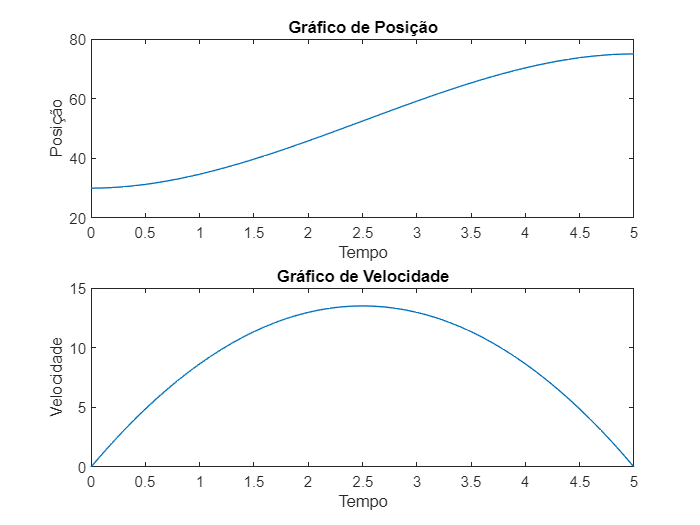

graf3ordPosVel(M,5)

### EXERCÍCIO 2

theta(t) = C0 + C1t + C2t^2 + C3t^3

Condição inicial: t = 0s --> 75° (posição)

75° = C0 + C1*0 + C2*0^2 + C3*0^3       --> C0 = 75°

Condição final: t = 3s --> 105° (posição)

105° = 75 + C1*5 + C2*5^2 + C3*5^3

30° = C1*3 + C2*3^2 + C3*3^3  --> 9*C2 + 27*C3 = 30      Equação (1)

Derivada 1ª de theta(t)

theta_ponto(t) = C1 + 2*C2*t + 3*C3*t^2

Condição inicial: t = 0 --> 0°/s (velocidade)

0°/s = C1 + 2*C2*0 + 3*C3*0^2     --->   C1 = 0

Condição inicial: t = 5 --> 0°/s (velocidade)

0°/s =  2*C2*3 + 3*C3*3^2

6*C2 + 27*C3 = 0              Equação (2) 

Sistema (Equações 1 e 2)

9*C2 + 27*C3 = 30

6*C2 + 27*C3 = 0

% [9, 27; 6, 27]*[C2; C3] = [30; 0]
C = inv([9, 27; 6, 27]) * [30; 0]

C =    10.0000
   -2.2222


C2 = 10

C3 = -2.2222

M = coef3(75, 105, 3)

M =    75.0000
         0
   10.0000
   -2.2222


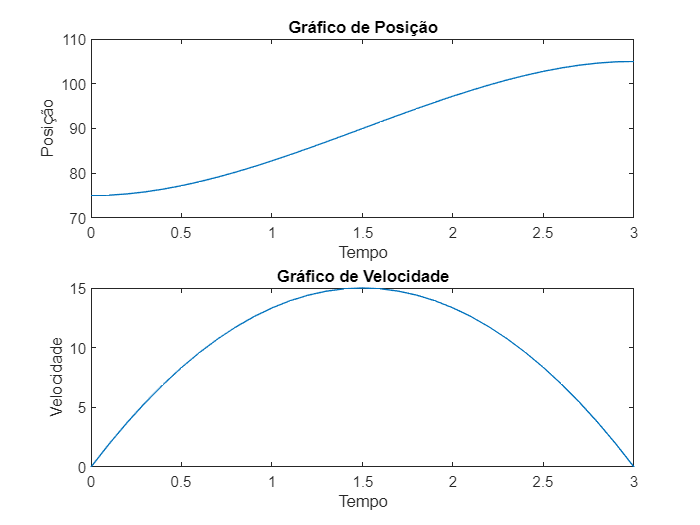

graf3ordPosVel(M,3)

### EXERCÍCIO 3

theta(t) = C0 + C1*t + C2*t^2 + C3*t^3 + C4*t^4 + C5*t^5

                  |                     ti = 0                                     tf = 5                  |

Condições |              theta(ti) = 30                         theta(tf) = 75            |

   Iniciais    |         theta_ponto(ti) = 0                 theta_ponto(tf) = 0       |

                  | theta_2_ponto(ti) = 5°/s^2     theta_2_ponto(tf) = -5°/s^2  |

Condição inicial: t = 0s --> 30° (posição)

30° = C0 + C1*0 + C2*0^2 + C3*0^3 + C4*0^4 + C5*0^5       --> C0 = 30

Condição inicial: t = 0s --> 0°/s (posição)

0°/s =  C1*0 + 2*C2*0 + 3*C3*0^2 + 4*C4*0^3 + 5*C5*0^4       --> C1 = 0

Condição inicial: t = 0s --> 5°/s^2 (posição)

5°/s^2 =  2*C2 + 6*C3*0 + 12*C4*0^2 + 20*C5*0^3 

2*C2 = 5  -->   C2 = 2,5

tf = 5s

theta(5) = 30 + 0*5 + 2,5*5^2 + C3*5^3 + C4*5^4 + C5*5^5

75 = 30 + 0 + 62,5 + 125*C3 + 625*C4 + 3125*C5

125*C3 + 625*C4 + 3125*C5 = -17,5                             Equação(1)

theta_ponto(5) = 0 = 0 + 2(2,5)(5) + 3*C3*5^2 + 4*C4*5^3 + 5*C5*5^4

75*C3 + 500*C4 + 3125*C5 = -25                             Equação(2)

theta_2_ponto(5) = -5 = 2(2,5)(5) + 6*C3*5 + 12*C4*5^2 + 20*C5*5^3

30*C3 + 300*C4 + 2500*C5 = -10                             Equação(3)

Sistema (Equações 1, 2 e 3)

125*C3 + 625*C4 + 3125*C5 = -17,5

75*C3 + 500*C4 + 3125*C5 = -25

30*C3 + 300*C4 + 2500*C5 = -10

C = inv([125, 625, 3125; 75, 500, 3125; 30, 300, 2500]) * [-17.5; -25; -10]

C =     1.6000
   -0.5800
    0.0464


C3 = 1,6

C4 = -0,58

C5 = 0,0464

M = coef5(30,75,5,5)

M =    30.0000
         0
    2.5000
    1.6000
   -0.5800
    0.0464


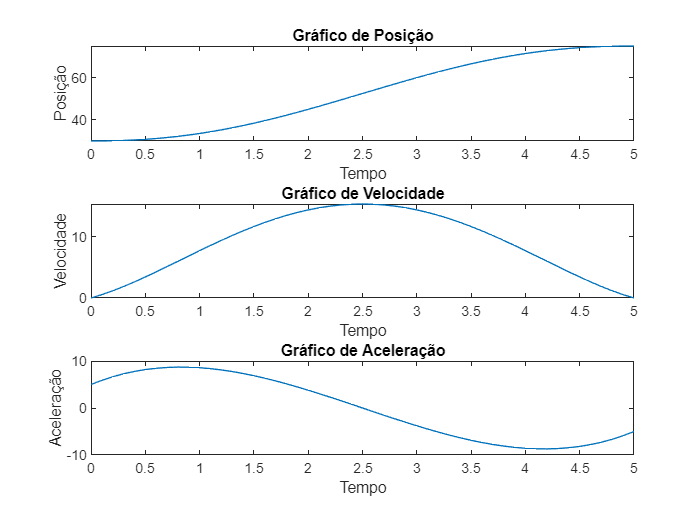

graf5ordPosVelAcel(M,5)

### EXERCÍCIO 4

Seja um manipulador antropomórfico que necessita mover todas as juntas em 7 segundos ate um ponto especificado 

• A primeira junta deve ir de 0º a 50º por um polinômio de ordem 3 

theta(t) = C0 + C1*t + C2*t^2 + C3*t^3

                  |                   ti = 0s                                   tf = 7s                  |

Condições |              theta(ti) = 0°                         theta(tf) = 50°           |

   Iniciais    |         theta_ponto(ti) = 0                 theta_ponto(tf) = 0       |

Condição inicial: t = 0s --> 0° (posição)

0° = C0 + C1*0 + C2*0^2 + C3*0^3       --> C0 = 0°

Condição final: t = 7s --> 50° (posição)

50° = 0 + C1*7 + C2*7^2 + C3*7^3

50° = C1*7 + C2*7^2 + C3*7^3  --> 49*C2 + 343*C3 = 50      Equação (1)

Derivada 1ª de theta(t)

theta_ponto(t) = C1 + 2*C2*t + 3*C3*t^2

Condição inicial: t = 0 --> 0°/s (velocidade)

0°/s = C1 + 2*C2*0 + 3*C3*0^2     --->   C1 = 0

Condição inicial: t = 7s --> 0°/s (velocidade)

0°/s =  2*C2*7 + 3*C3*7^2

14*C2 + 147*C3 = 0              Equação (2) 

Sistema (Equações 1 e 2)

49*C2 + 343*C3 = 50

14*C2 + 147*C3 = 0

C = inv([49, 343; 14, 147]) * [50; 0]

C =     3.0612
   -0.2915


C2 = 3,0612

C3 = -0.2915

Junta 1 -> theta(t) = 3,0612*t^2 - 0.02915*t^3

M = coef3(0,50,7)

M =          0
    0.0000
    3.0612
   -0.2915


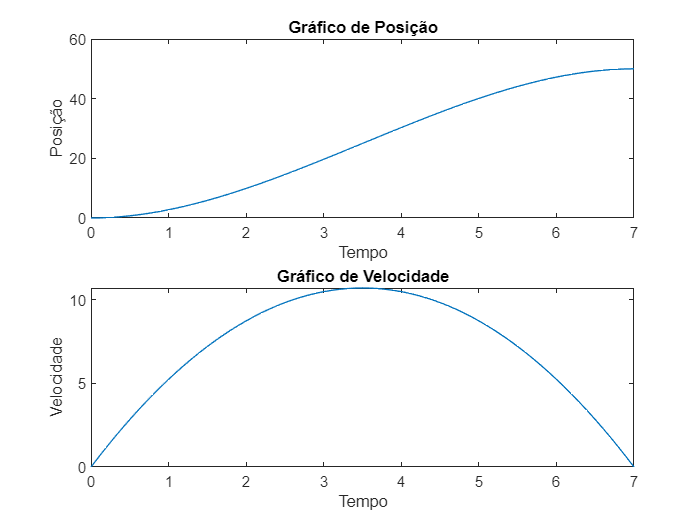

graf3ordPosVel(M,7)

• A segunda junta deve ir de 0º a 90º por um polinômio de ordem 5, com aceleração e desaceleração igual a 0.

theta(t) = C0 + C1*t + C2*t^2 + C3*t^3 + C4*t^4 + C5*t^5

                  |                   ti = 0s                                   tf = 7s                  |

Condições |              theta(ti) = 0°                         theta(tf) = 90°           |

   Iniciais    |       theta_ponto(ti) = 0°/s            theta_ponto(tf) = 0°/s      |

                  | theta_2_ponto(ti) = 0°/s^2     theta_2_ponto(tf) = 0°/s^2   |

Condição inicial: t = 0s --> 0° (posição)

0° = C0 + C1*0 + C2*0^2 + C3*0^3 + C4*0^4 + C5*0^5       --> C0 = 0

Condição inicial: t = 0s --> 0°/s (posição)

0°/s =  C1*0 + 2*C2*0 + 3*C3*0^2 + 4*C4*0^3 + 5*C5*0^4       --> C1 = 0

Condição inicial: t = 0s --> 0°/s^2 (posição)

0°/s^2 =  2*C2 + 6*C3*0 + 12*C4*0^2 + 20*C5*0^3 

2*C2 = 0  -->   C2 = 0

tf = 7s

theta(5) = 0 + 0*7 + 0*7^2 + C3*7^3 + C4*7^4 + C5*7^5

90 = 0 + 0 + 0 + 343*C3 + 2401*C4 + 16807*C5

343*C3 + 2401*C4 + 16807*C5 = 90                             Equação(1)

theta_ponto(5) = 0 = 0 + 0 + 3*C3*7^2 + 4*C4*7^3 + 5*C5*7^4

147*C3 + 1372*C4 + 12005*C5 = 0                              Equação(2)

theta_2_ponto(5) = 0 = 0 + 6*C3*7 + 12*C4*7^2 + 20*C5*7^3

42*C3 + 588*C4 + 6860*C5 = 0                             Equação(3)

Sistema (Equações 1, 2 e 3)

343*C3 + 2401*C4 + 16807*C5 = 90

147*C3 + 1372*C4 + 12005*C5 = 0

42*C3 + 588*C4 + 6860*C5 = 0

C = inv([343, 2401, 16807; 147, 1372, 12005; 42, 588, 6860]) * [90; 0; 0]

C =     2.6239
   -0.5623
    0.0321


Junta 2 -> theta(t) = 2.623t^3 - 0.5623*t^4 + 0.0321*t^5

M = coef5(0,90,7,0)

M =          0
         0
         0
    2.6239
   -0.5623
    0.0321


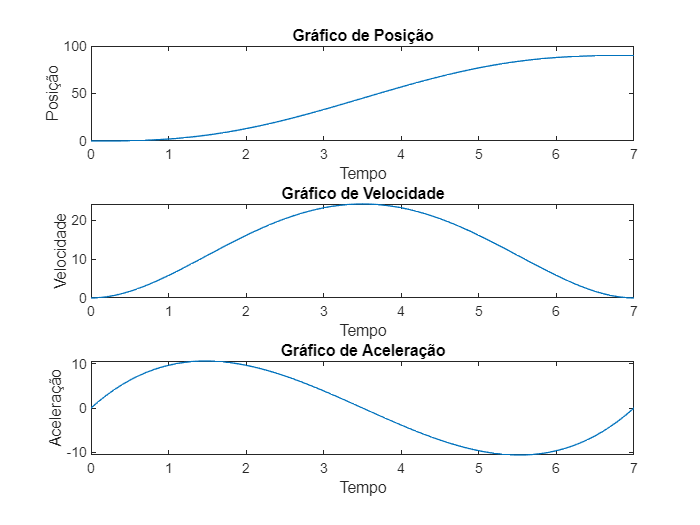

graf5ordPosVelAcel(M,7)

• A terceira junta deve ir de 0º a 10º por um polinômio de ordem 5, com aceleração e desaceleração igual a 0. Esboce graficamente os ângulos, velocidades e aceleração ao longo do tempo.

theta(t) = C0 + C1*t + C2*t^2 + C3*t^3 + C4*t^4 + C5*t^5

                  |                   ti = 0s                                   tf = 7s                  |

Condições |              theta(ti) = 0°                         theta(tf) = 10°           |

   Iniciais    |         theta_ponto(ti) = 0                 theta_ponto(tf) = 0       |

                  | theta_2_ponto(ti) = 0°/s^2     theta_2_ponto(tf) = 0°/s^2   |

Condição inicial: t = 0s --> 0° (posição)

0° = C0 + C1*0 + C2*0^2 + C3*0^3 + C4*0^4 + C5*0^5       --> C0 = 0

Condição inicial: t = 0s --> 0°/s (posição)

0°/s =  C1*0 + 2*C2*0 + 3*C3*0^2 + 4*C4*0^3 + 5*C5*0^4       --> C1 = 0

Condição inicial: t = 0s --> 0°/s^2 (posição)

0°/s^2 =  2*C2 + 6*C3*0 + 12*C4*0^2 + 20*C5*0^3 

2*C2 = 0  -->   C2 = 0

tf = 7s

theta(5) = 0 + 0*7 + 0*7^2 + C3*7^3 + C4*7^4 + C5*7^5

10 = 0 + 0 + 0 + 343*C3 + 2401*C4 + 16807*C5

343*C3 + 2401*C4 + 16807*C5 = 10                             Equação(1)

theta_ponto(5) = 0 = 0 + 0 + 3*C3*7^2 + 4*C4*7^3 + 5*C5*7^4

147*C3 + 1372*C4 + 12005*C5 = 0                              Equação(2)

theta_2_ponto(5) = 0 = 0 + 6*C3*7 + 12*C4*7^2 + 20*C5*7^3

42*C3 + 588*C4 + 6860*C5 = 0                             Equação(3)

Sistema (Equações 1, 2 e 3)

343*C3 + 2401*C4 + 16807*C5 = 10

147*C3 + 1372*C4 + 12005*C5 = 0

42*C3 + 588*C4 + 6860*C5 = 0

C = inv([343, 2401, 16807; 147, 1372, 12005; 42, 588, 6860]) * [10; 0; 0]

C =     0.2915
   -0.0625
    0.0036


Junta 3 -> theta(t) = 0.2915t^3 - 0.0625*t^4 + 0.0036*t^5

M = coef5(0,10,7,0)

M =          0
         0
         0
    0.2915
   -0.0625
    0.0036


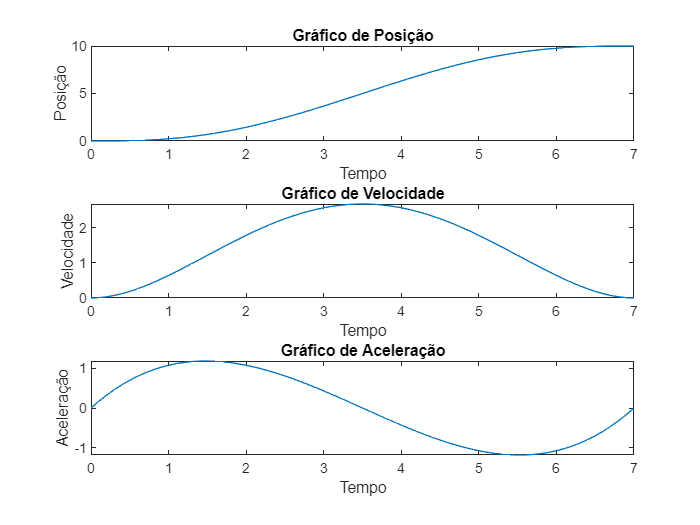

graf5ordPosVelAcel(M,7)

## **Polinomios de ordem superior**

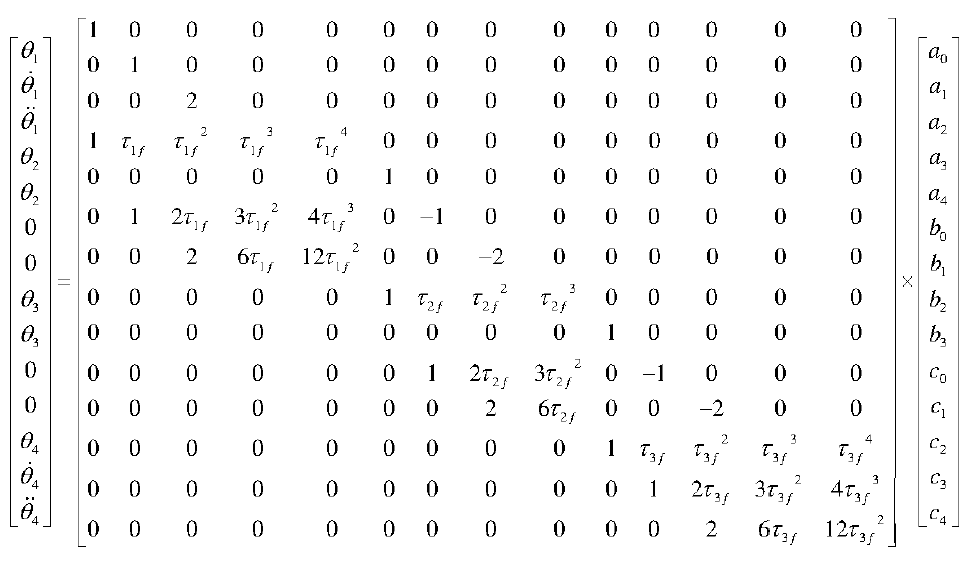

t1f = 2;
t2f = 4;
t3f = 2;

theta1 = 30;
theta1_ponto = 0;
theta1_2pontos = 0;
theta2 = 50;
theta3 = 90;
theta4 = 70;
theta4_ponto = 0;
theta4_2pontos = 0;

L1 = [1 zeros(1,13)];
L2 = [0 1 zeros(1,12)];
L3 = [0 0 2 zeros(1,11)];
L4 = [1 t1f t1f^2 t1f^3 t1f^4 zeros(1,9)];
L5 = [zeros(1,5) 1 zeros(1,8)];
L6 = [0 1 2*t1f 3*t1f^2 4*t1f^3 0 -1 zeros(1,7)];
L7 = [0 0 2 6*t1f 12*t1f^2 0 0 -2 zeros(1,6)];
L8 = [zeros(1,5) 1 t2f t2f^2 t2f^3 zeros(1,5)];
L9 = [zeros(1,9) 1 zeros(1,4)];
L10 = [zeros(1,6) 1 2*t2f 3*t2f^2 0 -1 0 0 0];
L11 = [zeros(1,7) 2 6*t2f 0 0 -2 0 0];
L12 = [zeros(1,9) 1 t3f t3f^2 t3f^3 t3f^4];
L13 = [zeros(1,10) 1 2*t3f 3*t3f^2 4*t3f^3];
L14 = [zeros(1,11) 2 6*t3f 12*t3f^2];

M = [L1; L2; L3; L4; L5; L6; L7; L8; L9; L10; L11; L12; L13; L14];
THETA = [theta1; theta1_ponto; theta1_2pontos; theta2; theta2; 0; 0; theta3; theta3; 0; 0; theta4; theta4_ponto; theta4_2pontos]

THETA =     30
     0
     0
    50
    50
     0
     0
    90
    90
     0


inv(M)*THETA

ans =    30.0000
         0
         0
    4.8810
   -1.1905
   50.0000
   20.4762
    0.7143
   -0.8333
   90.0000


valTheta = [30 50 90 70];
valT = [2 4 2];
Coef = CoefHighOrderPol434(valTheta, valT)

Coef =    30.0000
         0
         0
    4.8810
   -1.1905
   50.0000
   20.4762
    0.7143
   -0.8333
   90.0000
